## 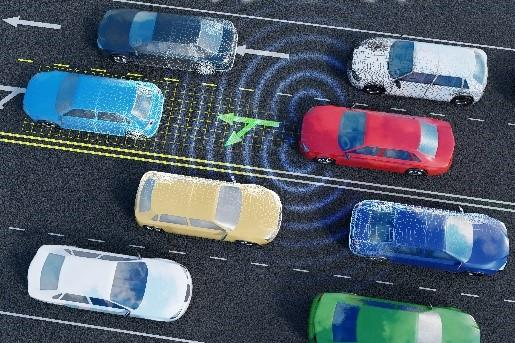

# Traffic Data Analysis for Modelling and Prediction of Traffic Scenario

####  Girolamo Oddo

***Work carried out in relation to the "Mathworks Innovation Excellence" initiative***

[*MathWorks Site*](https://it.mathworks.com/academia/matlab-engineering-project-ideas.html)* | *[*Project-specific Mathworks repository*](https://github.com/mathworks/MathWorks-Excellence-in-Innovation/tree/main/projects/Traffic%20Data%20Analysis%20for%20Modelling%20and%20Prediction%20of%20Traffic%20Scenarios)

*ctrl+f11 *to switch to full screen

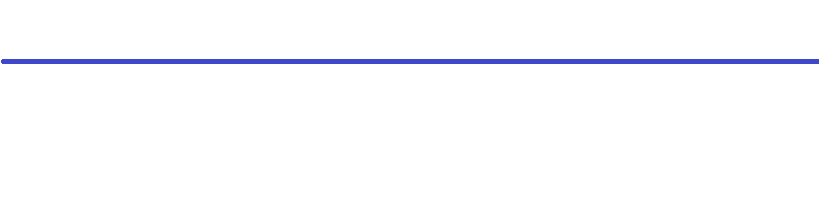

clear; clc; format long; 


## **Use this code to train a new NARX net**

### **Load the Datasets:**

Enter the name of the reference file in full format eg: NN-TARG.csv.

Pay attention to the dimensional agreement between Input and Target. They must have the same number of rows.

Targets must be expressed in binary form eg: 'Turn'= 0,0,1,0,0,0,0,0,0,0

*[In the proposed work was used: *

* NN-IN.xlsx   - input time series.*

* NN-TARG.csv - feedback time series.]*

%   NN-IN   - input time series.
%   NN-TARG - feedback time series.
ININ="NN-IN.xlsx";
TARGTARG="NN-TARG.csv";

IN = readmatrix(ININ);
TARG = readmatrix(TARGTARG);
% IN = readmatrix('NN-IN.xlsx');
% TARG = readmatrix('NN-TARG.csv');

X = tonndata(IN,false,false);
T = tonndata(TARG,false,false);


### **Choose the training function: **

**Scaled conjugate gradient backpropagation:**

`trainscg` can train any network as long as its weight, net input, and transfer functions have derivative functions. Backpropagation is used to calculate derivatives of performance `perf` with respect to the weight and bias variables `X`.

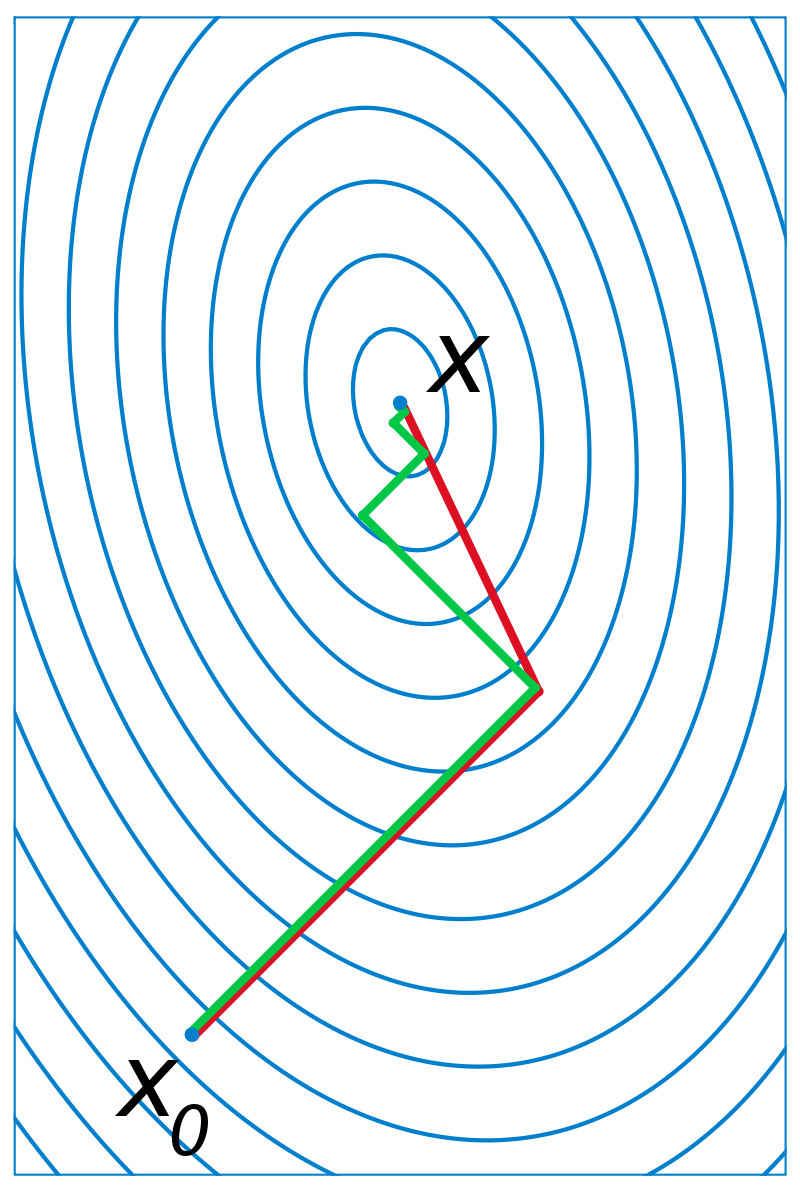

**Levenberg-Marquardt backpropagation:**

`trainlm` is often the fastest backpropagation algorithm in the toolbox, and is highly recommended as a first-choice supervised algorithm, although it does require more memory than other algorithms.

Like the quasi-Newton methods, the Levenberg-Marquardt algorithm was designed to approach second-order training speed without having to compute the Hessian matrix.

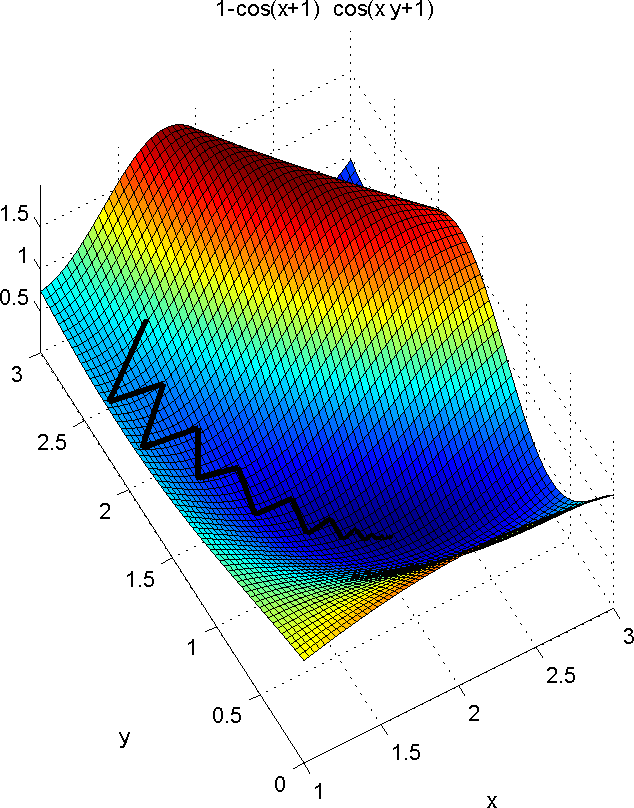

**Resilient backpropagation:**

Multilayer networks typically use sigmoid transfer functions in the hidden layers. These functions are often called “squashing” functions, because they compress an infinite input range into a finite output range. Sigmoid functions are characterized by the fact that their slopes must approach zero as the input gets large. This causes a problem when you use steepest descent to train a multilayer network with sigmoid functions, because the gradient can have a very small magnitude and, therefore, cause small changes in the weights and biases, even though the weights and biases are far from their optimal values.

The purpose of the resilient backpropagation (Rprop) training algorithm is to eliminate these harmful effects of the magnitudes of the partial derivatives. Only the sign of the derivative can determine the direction of the weight update; the magnitude of the derivative has no effect on the weight update. 

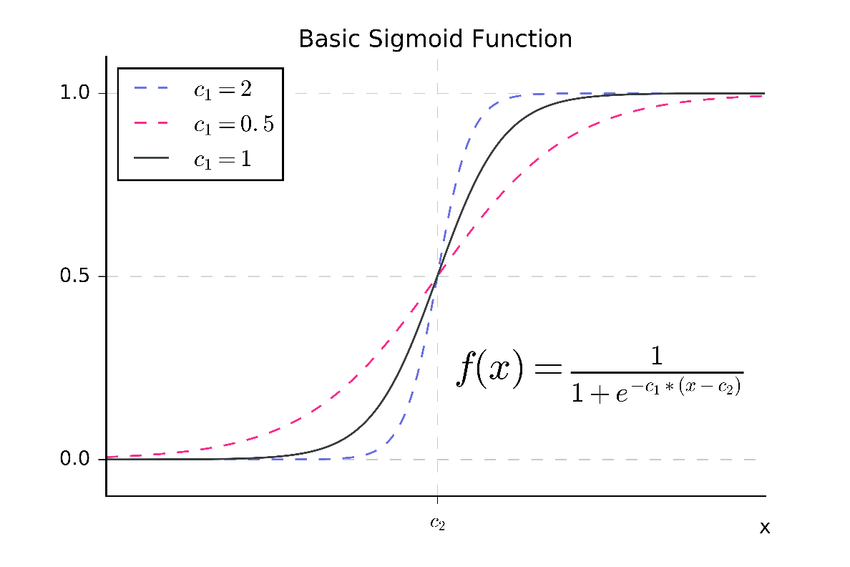

Many other training functions are available in MATLAB: [Training Functions for Multilayer Neural Network](https://it.mathworks.com/help/deeplearning/ug/choose-a-multilayer-neural-network-training-function.html)

*[In the proposed work was used: Scaled conjugate gradient backpropagation]*

% Choose a Training Function

HH= "trainscg";

% 'trainscg' uses less memory. Suitable in low memory situations.
%trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
%trainFcn = 'trainlm'; % Levenberg-Marquardt backpropagation.
%trainFcn = 'trainrp'; % Resilient backpropagation.
trainFcn = HH;


### **Choose the Delay value: **

Varying the delay means varying the problem you are going to solve according to the following form:

*  𝑦(𝑡) = 𝑓(x (t-1),...,x (t-d), y (t-1),...,y (t-d))*

*[In the proposed work was used: 2]*

DD=2;

% Create a Nonlinear Autoregressive Network with External Input
inputDelays = 1:DD;
feedbackDelays = 1:DD;


### Choose the number of neurons in the Idden Layer (N):

Input Layer ∈ **R**^4   ->  Idden Layer ∈ **R**^N  ->   Output Layer ∈ **R**^10

*[In the proposed work was used: 10]*

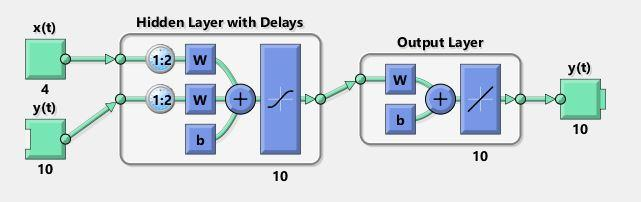

hiddenLayerSize = 10;
net = narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);

% Prepare the Data for Training and Simulation
[x,xi,ai,t] = preparets(net,X,{},T);


### Choose the division of data for Training, Validation, Testing:

The following distribution is generally used:

70% Training  15% Validation  15% Testing

*[In the proposed work was used: 70;15;15]*


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio =70/100;%70/100
net.divideParam.valRatio  = 15/100;%15/100
net.divideParam.testRatio = 15/100;%15/100

tic


% Train the Network
[net,tr] = train(net,x,t,xi,ai);

% Test the Network
y = net(x,xi,ai);
e = gsubtract(t,y);

### Extract from the code:

### Choose results to display:

PLOTTRAINST=true;PERFPLOT=true; NETPLOT=true; ERRHIST=true;CONFPLOT=false;

# RUN the whole code:

### Results:

toc

Elapsed time is 13.687788 seconds.


% Plots
fprintf(' Training function: %s\n Delay value:%d\n Neurons in the Idden Layer: %d\n Data division: %d,%d,%d\n',HH,DD,hiddenLayerSize,(net.divideParam.trainRatio)*100,(net.divideParam.valRatio)*100,(net.divideParam.testRatio)*100);

 Training function: trainscg
 Delay value:2
 Neurons in the Idden Layer: 10
 Data division: 70,15,15


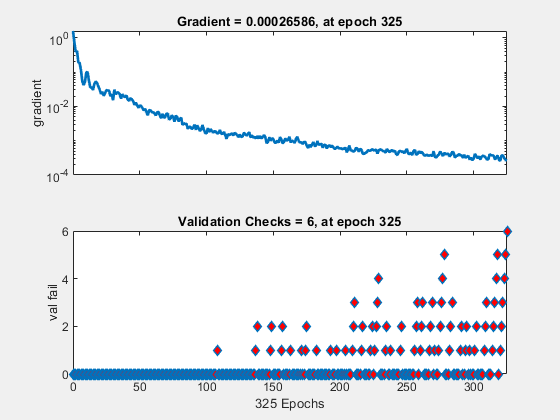



if PLOTTRAINST==1
plottrainstate(tr)
end

MSE: 


   0.009643531561302



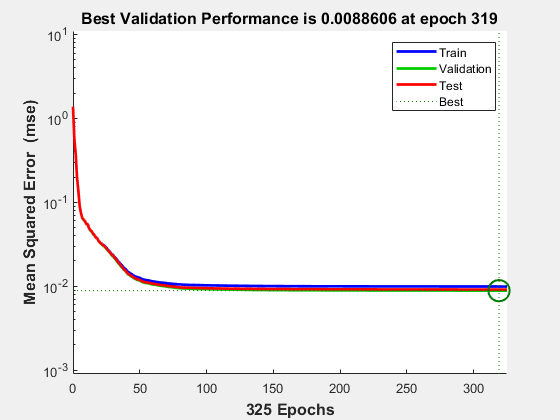


if PERFPLOT==1
fprintf('MSE: \n')
performance = perform(net,t,y); disp(performance)
plotperform(tr);
end

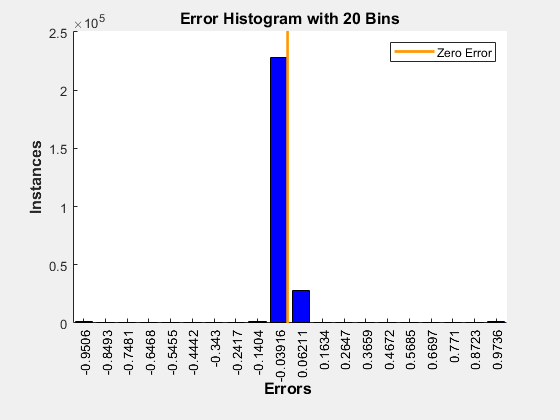


if NETPLOT==1
% View the Network
view(net)
end

if ERRHIST==1
ploterrhist(e)   
end


if CONFPLOT==1
plotconfusion(t,y)
end

% Closed Loop Network
% Use this network to do multi-step prediction.
% The function CLOSELOOP replaces the feedback input with a direct
% connection from the output layer.
netc = closeloop(net);
netc.name = [net.name ' - Closed Loop'];
%view(netc)
[xc,xic,aic,tc] = preparets(netc,X,{},T);
yc = netc(xc,xic,aic);
closedLoopPerformance = perform(net,tc,yc);

% Step-Ahead Prediction Network
nets = removedelay(net);
nets.name = [net.name ' - Predict One Step Ahead'];
%view(nets)
[xs,xis,ais,ts] = preparets(nets,X,{},T);
ys = nets(xs,xis,ais);
stepAheadPerformance = perform(nets,ts,ys);



All texts come from MathWorks websites

Images taken from:

[Conjugate gradient method](https://en.wikipedia.org/wiki/Conjugate_gradient_method)

[levenberg marquardt](https://docs.mrpt.org/reference/latest/page_tutorial_math_levenberg_marquardt.html)

[Basic sigmoid function](https://www.researchgate.net/figure/A-Basic-sigmoid-function-with-two-parameters-c1-and-c2-as-commonly-used-for-subitizing_fig2_325868989)